% This tutorial takes an example cluster assignment that spans multiple
% topological levels (i.e. community size varies in a continuous manner) or
% temporal networks (there's high correspondence across neighboring
% columns)

% Notes: make sure this toolbox and subfolders is on the MATLAB path
% (https://www.mathworks.com/help/matlab/ref/addpath.html)

clear;close all;clc; % this just clears the workspace, command window and close all figures to start clean

% Load example data
load('./ExampleData/example_clusters_ordinal.mat','example_clusters'); % Nnodes x Nlevels
input_check_HSB(example_clusters); % will produce an error if your input is problematic

%% Step 1: Generate a coassignment matrix that shows the frequency of coassignment across clusters
% N.B. can be used as input for hierarchicalConsensus() but it usually
% requires a lot of levels(columns)
C = coclassificationMatrix(example_clusters); % would be the same if you used sorted_clusters but the input needs to be double(sorted_clusters)
levels = 1:size(example_clusters,2); % replace if you have any meaningful value for the levels, e.g. the number of communities, the resolution parameter etc.

% sanity check: visualize the co-assignment matrix sorted by the assignment
% of each level, note that this is NOT your original matrix input to
% generate the community assignment but the frequency of coassignment of
% nodes


figure;
disp('Paused. Press Any Key to Continue and CTRL+C to quit');

Paused. Press Any Key to Continue and CTRL+C to quit


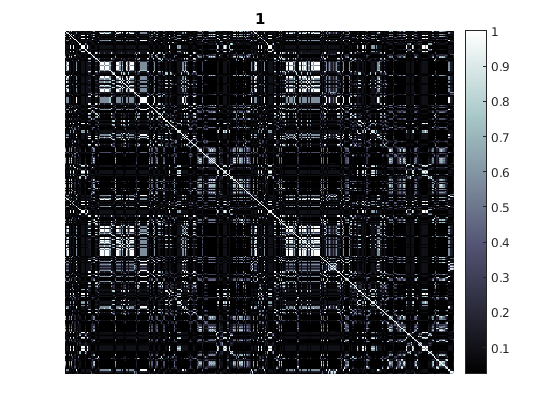


for k = 1:size(example_clusters,2)
    [~,sortid] =sort(example_clusters(:,k));
    imagesc(C(sortid,sortid));colormap(bone);
    colorbar;
    axis off;
    title(levels(k));    
    pause;
    clf;
end


% You should see some kind of block organization.

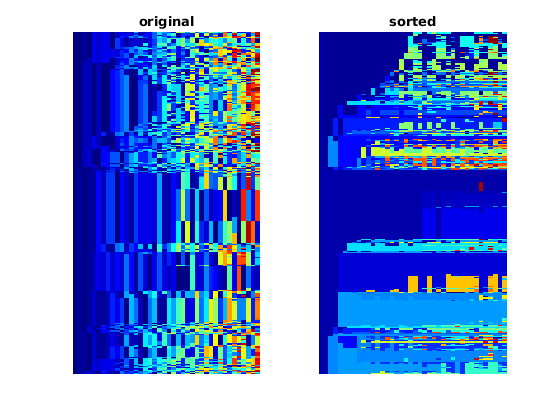

%% Step 2: Sort the community numbers to match between the columns as best as possible
minsize = 2;
sorted_clusters  = postprocess_categorical_multilayer(example_clusters);  % sort across level to have some consistency across columns
sorted_clusters = remove_singleton(sorted_clusters,minsize); % remove communities smaller than a size

% sanity check plot: you should see some consistency across columns
figure;
subplot(1,2,1);
imagesc(sortrows(example_clusters,1:size(example_clusters,2)));axis off
colormap(jet);
title('original');
subplot(1,2,2);
imagesc(sortrows(sorted_clusters,1:size(sorted_clusters,2)));axis off
colormap(jet);
title('sorted');


n_unique_clusters = max(sorted_clusters(:)) % display how many unique clusters you have

n_unique_clusters = 47

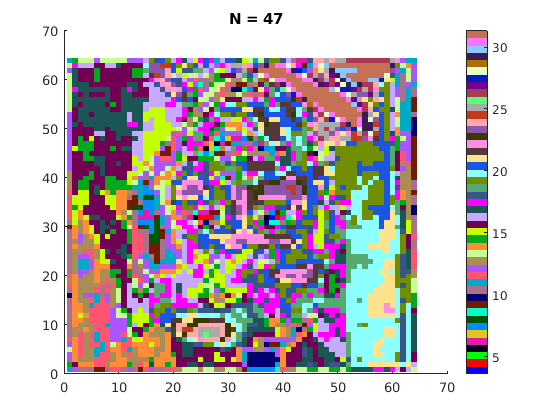

%% Step 3 (no template): Assign maximally different colors to the block
nameoption = 1;% 1: random colors, 3: using a color template

[CWro,SortConsRO] = assign_network_colors(sorted_clusters,nameoption); % make sure here you used "sorted_clusters" if you use "example_clusters" which was not sorted it won't work



% Now CWro is a structure with two fields, "Nets" and "cMap"
% where Nets is the name of the clusters, right now just 1 to n_unique_clusters, 
% cMap is the colormap of each cluster n_unique_clusters x 3 [R G B] each
% value is between 0 and 1

% SortConsRO is the reordered networks such that similar names will be
% ordered together and the order is consistent with the order of template
% (see below)

% You may wish to it now so next time we can start with step 3
save('./Results/example_results.mat','SortConsRO','CWro');

%% Step 3 (with template): Assign colors with a CIFTI template (when the node is surface parcels)
% N.B. this needs cifti-matlab-master to be on the path (included at
% ./ExternalFunctions)
nameoption = 3;% 1: random colors, 3: using a color template
templatepath  ='./Templates/Gordon2017_17Networks.dlabel.nii'; % replace with your template path, some are provided in ./Templates, it has to be a .dlabel.nii file to get the network names
parcelpath = './Parcels/Gordon333.dtseries.nii' % replace with your parcel path, data size should match exactly with the template path

parcelpath = './Parcels/Gordon333.dtseries.nii'

% dice similarity to network
Network 1: Default, Default = 0.68 , Ventral Attention = 0.14 , Fronto-parietal = 0.09 ,
Network 2: Auditory, Auditory = 0.65 , Ventral SM = 0.05 , Cingulo-opercular = 0.04 ,
Network 3: Pre-motor, Pre-motor = 0.63 , Dorsal SM = 0.13 , SM Foot = 0.12 ,
Network 4: Visual, Visual = 0.66 , Medl Visual = 0.36 , Dorsal Attention = 0.16 ,
Network 5: SM Foot, SM Foot = 0.47 , Ventral SM = 0.39 , Dorsal SM = 0.38 ,
Network 6: Fronto-parietal, Fronto-parietal = 0.46 , Med Parietal = 0.21 , Salience = 0.09 ,
Network 7: Parieto-occipital, Parieto-occipital = 0.51 , Med Temporal 2 = 0.22 , Med Temporal = 0.08 ,
Network 8: Fronto-parietal, Fronto-parietal = 0.13 , Dorsal Attention = 0.01 , Cingulo-opercular = 0.01 ,
Network 9: Fronto-parietal, Fronto-parietal = 0.13 , Default = 0.05 , Salience = 0.03 ,
Network 10: Med Temporal, Med Temporal = 0.13 , Med Temporal 2 = 0.02 , Default = 0.00 ,
Network 11: Ventral Attention, Ventral Attention = 0.35 , Salience = 0.10 , Defaul

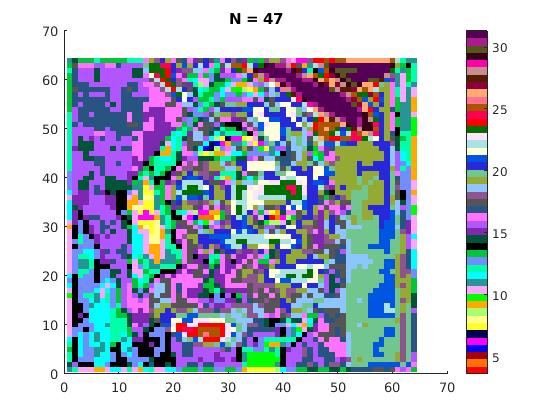

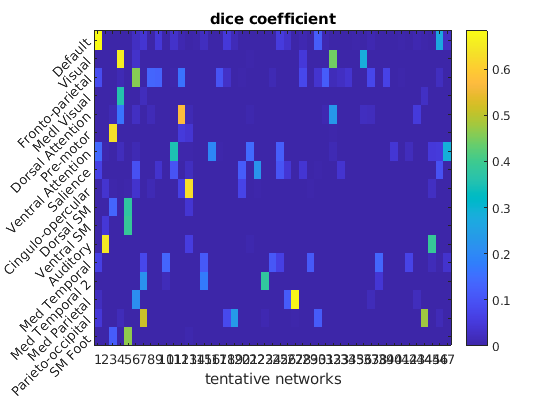


[CWro,SortConsRO] = assign_network_colors(sorted_clusters,nameoption,templatepath,parcelpath);


% You may wish to it now so next time we can start with step 4
save('./Results/example_results.mat','SortConsRO','CWro');


%% Step 4: Visualize the colors on the brain 
load('./Results/example_results.mat','SortConsRO','CWro'); % we are loading the sorted communites above
load('./Parcels/Parcels_Gordon.mat','Parcels');% load the "Parcels_*.mat" file that corresponds to your parcelpath above
levels = 1:size(SortConsRO,2); % replace if you have any meaningful value for the levels, e.g. the number of communities, the resolution parameter etc.
file_exten = './consensus_' % for saving the picture, replace with your saving path

file_exten = './consensus_'

Press on the block to switch between levels
, and press q for quit and s for saving figures when the mouse press is outside the blocks


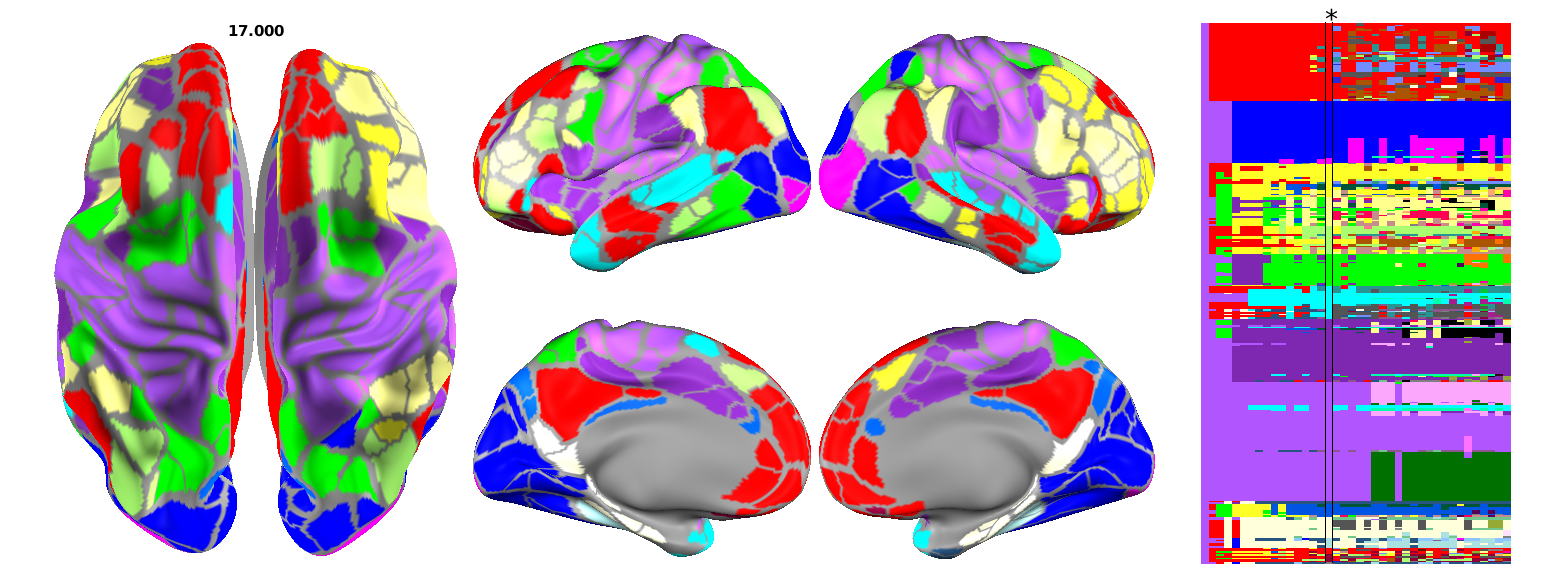


Explore_parcel_levels_HSB(SortConsRO,CWro.cMap,Parcels,levels,file_exten);


% The function above is an interactive plot for the different levels
% Press colormaps (the block on the right) to switch levels
% , and press q for quit and s for saving figures when the mouse press is outside the colormaps
